# Práctica 3 - Actividades II

### Actividad 2 - Oscilaciones amortiguadas

% Definición de la función simbólica x(t)
syms x(t)

% Definición de la primera derivada 
Dx = diff(x);
D2x = diff(x, 2);

% Condiciones iniciales
cond = [x(0) == 0, Dx(0) == 0];

% Velocidad angular
w = [0.5, 1.2, sqrt(2)];

% EDO 1
eqn = D2x + 2 * x == cos(w(1) * t);
y = dsolve(eqn, cond)

$$y = \begin{array}{l} \cos\left(\sqrt{2}\,t\right)\,\left(\frac{\sqrt{2}\,\cos\left(\sigma_{3}\right)}{\sigma_{1}}+\frac{\sqrt{2}\,\cos\left(\sigma_{4}\right)}{\sigma_{2}}\right)-\cos\left(\sqrt{2}\,t\right)\,\left(\frac{\sqrt{2}}{\sigma_{1}}+\frac{\sqrt{2}}{\sigma_{2}}\right)+\sin\left(\sqrt{2}\,t\right)\,\left(\frac{\sqrt{2}\,\sin\left(\sigma_{3}\right)}{\sigma_{1}}+\frac{\sqrt{2}\,\sin\left(\sigma_{4}\right)}{\sigma_{2}}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(2\,\sqrt{2}-1\right)\\ \sigma_{2}=2\,\left(2\,\sqrt{2}+1\right)\\ \sigma_{3}=t\,\left(\sqrt{2}-\frac{1}{2}\right)\\ \sigma_{4}=t\,\left(\sqrt{2}+\frac{1}{2}\right) \end{array}$$

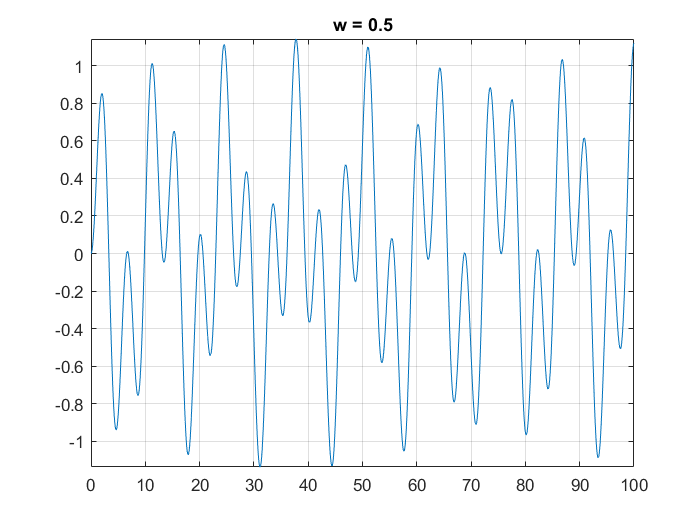

figure, fplot(y, [0, 100]), grid
title('w = 0.5')


% EDO 2
eqn2 = D2x + 2 * x == cos(w(2) * t);
y2 = dsolve(eqn2, cond)

$$y2 = \begin{array}{l} \cos\left(\sqrt{2}\,t\right)\,\left(\frac{\sqrt{2}\,\cos\left(\sigma_{3}\right)}{\sigma_{1}}+\frac{\sqrt{2}\,\cos\left(\sigma_{4}\right)}{\sigma_{2}}\right)-\cos\left(\sqrt{2}\,t\right)\,\left(\frac{\sqrt{2}}{\sigma_{1}}+\frac{\sqrt{2}}{\sigma_{2}}\right)+\sin\left(\sqrt{2}\,t\right)\,\left(\frac{\sqrt{2}\,\sin\left(\sigma_{3}\right)}{\sigma_{1}}+\frac{\sqrt{2}\,\sin\left(\sigma_{4}\right)}{\sigma_{2}}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(2\,\sqrt{2}-\frac{12}{5}\right)\\ \sigma_{2}=2\,\left(2\,\sqrt{2}+\frac{12}{5}\right)\\ \sigma_{3}=t\,\left(\sqrt{2}-\frac{6}{5}\right)\\ \sigma_{4}=t\,\left(\sqrt{2}+\frac{6}{5}\right) \end{array}$$

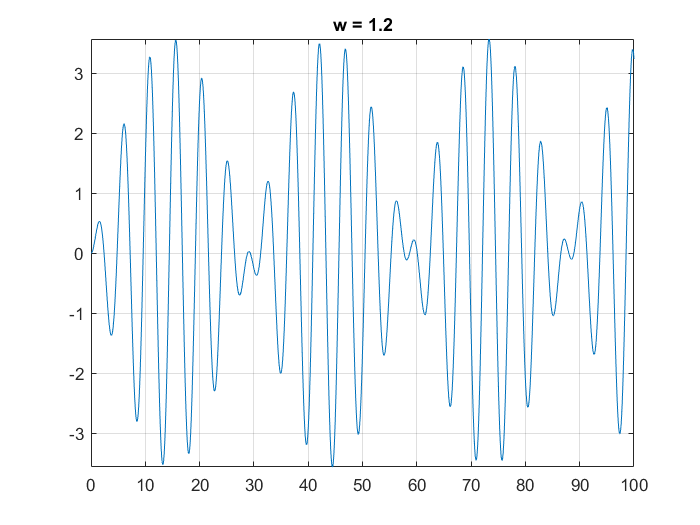

figure, fplot(y2, [0, 100]), grid
title('w = 1.2')


% EDO 3 (resonancia mecñanica)
eqn3 = D2x + 2 * x == cos(w(3) * t);
y3 = dsolve(eqn3, cond)

$$y3 = \frac{\cos\left(3\,\sqrt{2}\,t\right)}{16}-\frac{\cos\left(\sqrt{2}\,t\right)}{16}+\sin\left(\sqrt{2}\,t\right)\,\left(\frac{\sin\left(2\,\sqrt{2}\,t\right)}{8}+\frac{\sqrt{2}\,t}{4}\right)$$

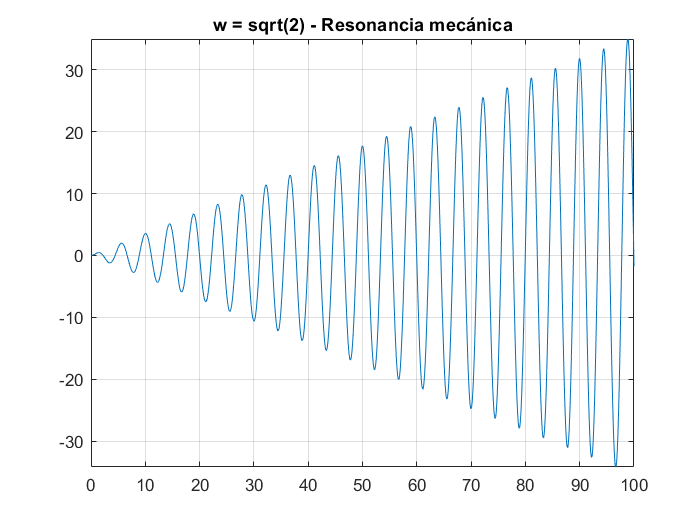

figure, fplot(y3, [0, 100]), grid
title('w = sqrt(2) - Resonancia mecánica')

### Actividad 3 - Epidemias. Modelos SIR

% Definición de las función simbólicas
syms S(t) I(t) R(t)

% Constantes
m = 0.01;
c = 0.02;

% Ecuaciones diferenciales
eqns = [diff(S) == -m * S, diff(I) == m * S - c * I, diff(R) == c * I];

% Condiciones iniciales
conds = [S(0) == 350, I(0) == 50, R(0) == 0];

% Soluciones
sol = dsolve(eqns, conds);
S = sol.S, I = sol.I, R = sol.R

$$S = 350\,{\mathrm{e}}^{-\frac{t}{100}}$$

$$I = 350\,{\mathrm{e}}^{-\frac{t}{100}}-300\,{\mathrm{e}}^{-\frac{t}{50}}$$

$$R = 300\,{\mathrm{e}}^{-\frac{t}{50}}-700\,{\mathrm{e}}^{-\frac{t}{100}}+400$$

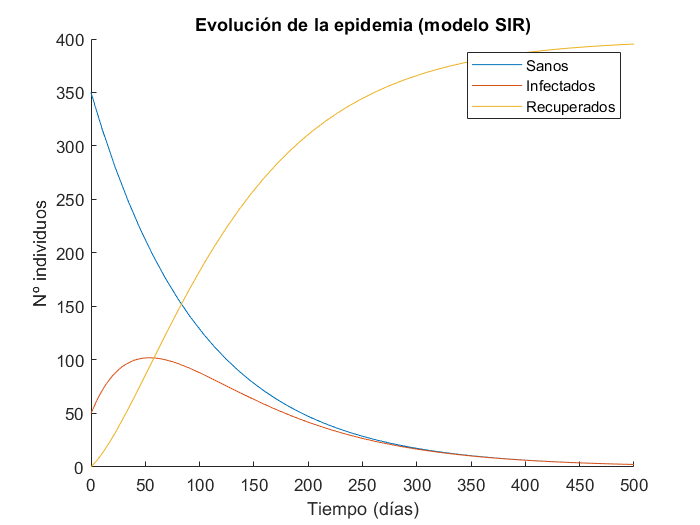


figure, hold on
fplot(S, [0, 500]), fplot(I, [0. 500]), fplot(R, [0, 500])
legend('Sanos', 'Infectados', 'Recuperados')
title('Evolución de la epidemia (modelo SIR)')
xlabel('Tiempo (días)'), ylabel('Nº individuos')